Returns All Important Control Functions for a gollowing Control Architecture

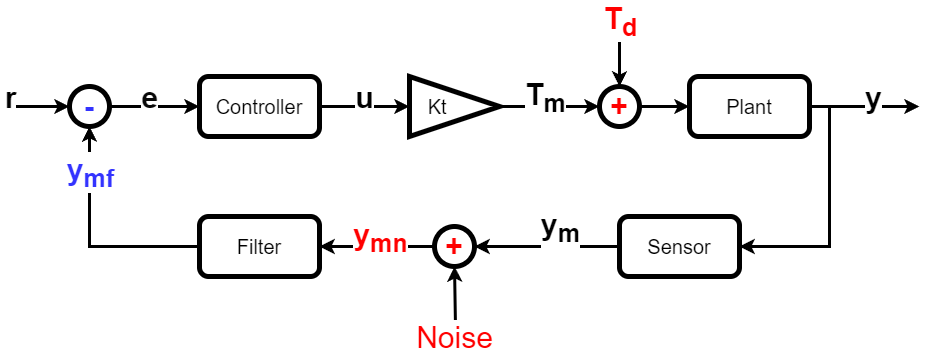

P - Plant Transfer Function

C - Controller Transfer Function

H - Sensor Transfer Function

F - Filter Transfer Function 

function [OUT] = get_design_functions(C, Kt, P, H, F)

OUT.C = C;
OUT.Kt = Kt;
OUT.P = P;
OUT.H = H;
OUT.F = F;

OUT.L = C*Kt*P*H*F; % Open Loop
OUT.L.Name = 'L_r2y';

OUT.T_r2e = feedback(1,OUT.L); %[r-->e]
OUT.T_r2e.Name = 'T_r2e';

OUT.T_r2u = OUT.T_r2e*C; %[r-->u]
OUT.T_r2u.Name = 'T_r2u';

OUT.T_r2y = OUT.T_r2u*Kt*P; %[r-->y]
OUT.T_r2y.name = 'T_r2y';

OUT.T_r2ym = OUT.T_r2y*H; %[r-->ym]
OUT.T_r2ym.Name = 'T_r2ym';

OUT.T_r2ymf = OUT.T_r2ym*F; %[r-->ymf]
OUT.T_r2ymf.Name = 'T_r2ymf';

OUT.T_d2y = OUT.T_r2e*P; %[d-->y]
OUT.T_d2y.Name = 'T_d2y';

OUT.T_d2u = OUT.T_d2y*H*F*C; %[d-->u]
OUT.T_d2u.Name = 'T_d2u';

OUT.T_n2u = feedback(F*C, Kt*P*H); %[n-->u]
OUT.T_n2u.Name = 'T_n2u';

OUT.T_n2y = feedback(F*C*Kt*P, H); %[n-->y]
OUT.T_n2y.Name = 'T_n2y';


OUT.T_ym2u = F*C; %[ym-->u]

if any([strcmp(class(C),'tf'), strcmp(class(F),'tf')]) 
    OUT.T_ym2u.Name = 'T_ym2u';
end

end